# Assignment - 1 Submission Example: Student 1

close all; clc; clear all;

## Open FEMM and make new document

% Assignment Query 1: Model PM
openfemm(); newdocument(0); name_femm = 'Test.fem';
mi_saveas([name_femm]);
% Setting Preferences
mi_probdef(0,'millimeters','planar',1E-8,10,30,0);

## Geometry

% Draw magnet
x1 = 5; x2 = -5; y1 = 1.25; y2 = -1.25;
mi_drawrectangle(x1,y1,x2,y2);

% Add material
Hc = 943000; %155319*sqrt(42), magnetic coercivity, A/m
uR = 1.05;  % remanent flux density, T
mi_addmaterial('N42', uR,uR, Hc, 0, 0); mi_getmaterial('Air'); 

% Assign Magnet Material
mi_clearselected(); 
mi_addblocklabel((x1+x2)/2,(y1+y2)/2); mi_selectlabel((x1+x2)/2,(y1+y2)/2);
mi_setblockprop('N42',1,0,'None',0,2,1);

% Drawing boundary
xx1 = 10; xx2 = -10; yy1 = 0; yy2 = 0; angle = 180;
mi_drawarc(xx1,yy1,xx2,yy2,angle,1); mi_drawarc(xx2,yy2,xx1,yy1,angle,1); 
mi_addboundprop('Air',0,0,0,0,0,0,0,0,0);
mi_selectarcsegment(0,10); mi_selectarcsegment(0,-10);
mi_setarcsegmentprop(5, 'Air', 0, 1); %group 1

% Assign Air
mi_clearselected();
mi_addblocklabel((x1+xx1)/2,(y1+yy1)/2);
mi_selectlabel((x1+xx1)/2,(y1+yy1)/2);
mi_setblockprop('Air',1,0,'<None>',0,0,1);

## Solve and obtain results + Assignment answers

ii) N42 signifies the grade of the Neodymium magnets. 

Neodymium magnets are graded by the maximum strength they can be magnetized to.

iii) Other grades are: N35, N40, N42, N45, N48, N50, N52, N54.

iv) The temperature limit for demagnetization in this particular grade of magnet is 310degC

v) Plot of Bx and By of the magnet at 0.1mm gap from the magnet

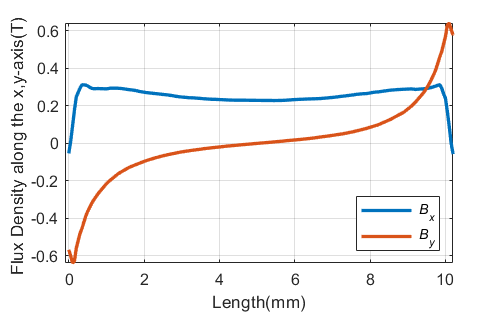

% Solve
mi_analyze(1); mi_loadsolution(); 
mo_clearblock();
k=1;
for i=(x2-0.1):0.05:(x1+0.1)
    B_xy = mo_getb(i,y1+0.1);
    B_x(k) = B_xy(1);
    B_y(k) = B_xy(2);
    k=k+1;
end
k=k-1;
for i=(y1+0.1):-0.05:(y2-0.1)
    B_xy = mo_getb(x1+0.1,i);
    B_x(k) = B_xy(1);
    B_y(k) = B_xy(2);
    k=k+1;
end
k=k-1;
for i=(x1+0.1):-0.05:(x2-0.1)
    B_xy = mo_getb(i,y2-0.1);
    B_x(k) = B_xy(1);
    B_y(k) = B_xy(2);
    k=k+1;
end
k=k-1;
for i=(y2-0.1):0.05:(y1+0.1)
    B_xy = mo_getb(x2-0.1,i);
    B_x(k) = B_xy(1);
    B_y(k) = B_xy(2);
    k=k+1;
end
l = 0:0.05:25.8;
plot(l,-B_x,l,B_y,'LineWidth', 2); xlim([-0.1 10.2]); grid on
xlabel('Length(mm)'); set(gcf,'Position',[0,0,400,250]);
ylabel('Flux Density along the x,y-axis(T) ');
lgd=legend('\it B_x', '\it B_y','Location','southeast');